Nbits = 1e6;
in = randi([0, 1], [Nbits, 1])*2-1;

Transmitter

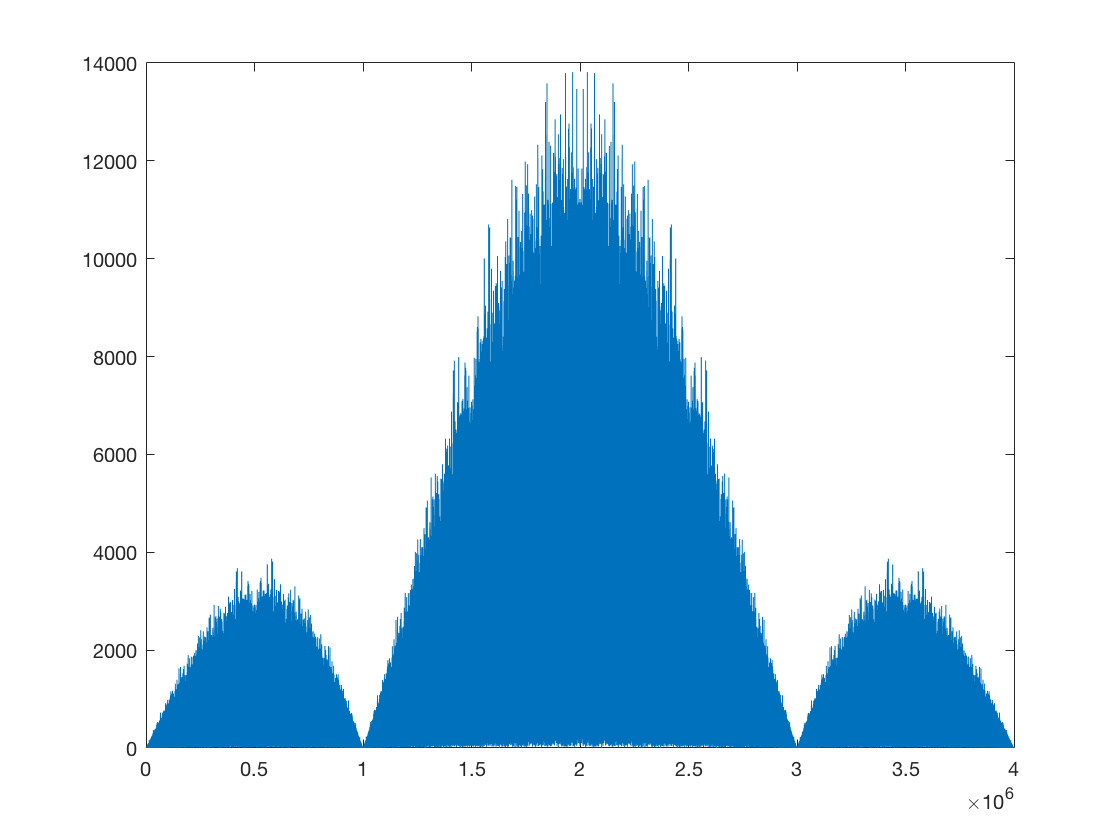

k = 2;
SpS = 2*k;
BpS = 1;
R_s = 1;
R_b = R_s * BpS;
B_sim = SpS * R_s;
v_t = zeros(Nbits*SpS, 1);

% NRZ
for a=0:Nbits-1
    for b=1:SpS
        v_t(a*SpS+b) = in(a+1);
    end
end

figure(1)
plot(1:Nbits*SpS, fftshift(abs(fft(v_t))))

Calcolo errori a diversi BER

err_arr = zeros(11, 1);
for www=2:12

Rumore Gaussiano Bianco

    EbN0 = (10^(www/10));
    P = mean(abs(in.^2));
    N0 = P/(EbN0*R_b);
    sigma = sqrt((N0/2)*B_sim);
    noise = sigma*randn(Nbits*SpS, 1);
    in_n = v_t+noise;

Filtro di Ricezione

    s_t = zeros(Nbits*SpS, 1);
    for a=1:4
        s_t(a) = 1;
    end
    S_f = (fft(s_t));
    H_rx = S_f;
    X_f = fft(in_n);
    Y_f = H_rx .* X_f;
    y = ifft(Y_f);

Sampling & Decision

Vediamo su quale bit è meglio campionare

    BERs = zeros(SpS, 1);
    for bit = 1:SpS
        r = y(bit:SpS:end) > 0;
        r = 2*r-1;
        err = in ~= r;
        BERs(bit) = sum(err)/Nbits;
    end
    BERs
    [m, i] = min(BERs);
    i

Scegliamo di campionare sul bit i-esimo (è sempre l'ultimo)

    r = y(i:SpS:end) > 0;
    r = 2*r-1;

Conteggio errori

    err = in ~= r;
    err_arr(www-1) = sum(err)/Nbits;
end

BERs =     0.4254
    0.2685
    0.1117
    0.0373


i = 4

BERs =     0.4328
    0.2617
    0.0909
    0.0227


i = 4

BERs =     0.4407
    0.2563
    0.0719
    0.0124


i = 4

BERs =     0.4510
    0.2536
    0.0549
    0.0060


i = 4

BERs =     0.4617
    0.2516
    0.0409
    0.0024


i = 4

BERs =     0.4724
    0.2510
    0.0283
    0.0008


i = 4

BERs =     0.4815
    0.2497
    0.0190
    0.0002


i = 4

BERs =     0.4887
    0.2500
    0.0116
    0.0000


i = 4

BERs =     0.4939
    0.2497
    0.0063
    0.0000


i = 4

BERs =     0.4972
    0.2511
    0.0031
    0.0000


i = 4

BERs =     0.4991
    0.2502
    0.0012
         0


i = 4

Plotting

err_arr

err_arr =     0.0373
    0.0227
    0.0124
    0.0060
    0.0024
    0.0008
    0.0002
    0.0000
    0.0000
    0.0000


figure(2)
semilogy(2:12, err_arr, 'ro')
hold on

Andamento teorico

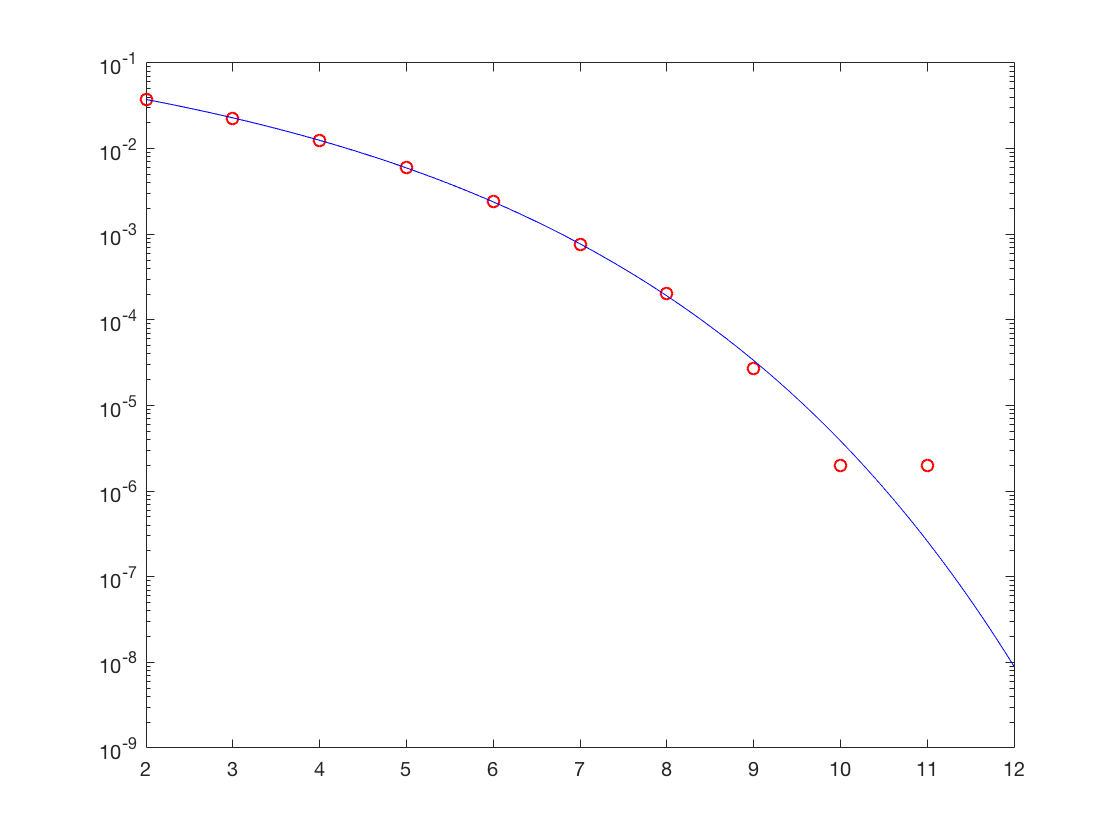

EbN0 = 2:0.1:12;
BER = 0.5*erfc(sqrt(10.^(EbN0/10)));
semilogy(EbN0, BER, 'b-')

Diagramma ad occhio

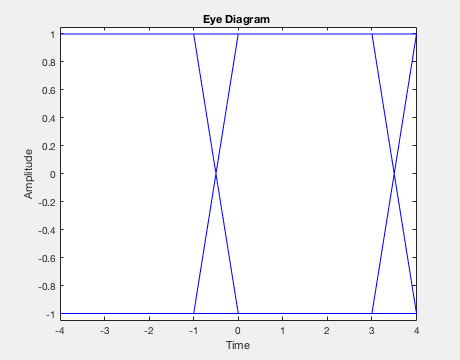

figure(3)
eyediagram(v_t(1:2000*SpS), 2*SpS, 2*SpS);

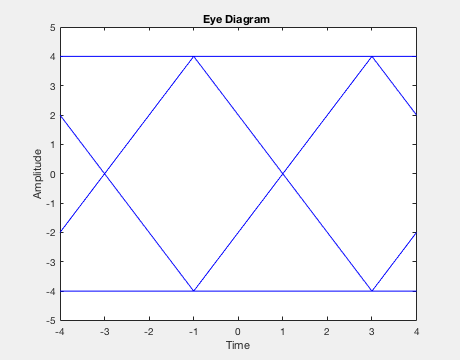



X_f_nn = fft(v_t);
Y_f_nn = H_rx .* X_f_nn;
y_nn = ifft(Y_f_nn);
figure(4)
eyediagram(y_nn(1:2000*SpS), 2*SpS, 2*SpS);